clear; close all; clc;

%% Load data
trainData = readtable('DailyDelhiClimateTrain.csv');
testData  = readtable('DailyDelhiClimateTest.csv');
trainData.date = datetime(trainData.date, "InputFormat", "yyyy-MM-dd");
testData.date  = datetime(testData.date, "InputFormat", "yyyy-MM-dd");

y_train = trainData.meantemp;
y_test  = testData.meantemp;

vars = trainData.Properties.VariableNames;

for i = 2:numel(vars)

    colName = vars{i};
    y = trainData.(colName);

    if ~isnumeric(y)
        fprintf("Column %s skipped (not numeric).\n", colName);
        continue;
    end

    % STL-style decomposition using trenddecomp
    % 365 = daily data with yearly seasonality
    [LT, ST, R] = trenddecomp(y, "stl", 365);

    resid = R;

    % 3-sigma threshold
    threshold = 3 * std(resid, "omitnan");
    outliers = abs(resid) > threshold;

    nOut = nnz(outliers);
    fprintf("Column %s: detected %d outliers.\n", colName, nOut);

    % ---- PRINT OUTLIER INFO (this is where it goes) ----
    if nOut > 0
        idx = find(outliers);      % row indices of outliers
        times = trainData{idx, 1}; % date column
        values = y(idx);           % original values
        resvals = resid(idx);      % residuals

        fprintf("  Outlier details:\n");
        for k = 1:nOut
            fprintf("    Row %d | Date %s | Value = %.3f | Residual = %.3f\n", ...
                idx(k), string(times(k)), values(k), resvals(k));
        end
    end
    % -----------------------------------------------------

    % Interpolate to replace outliers
    y_clean = y;
    idx_valid = find(~outliers);
    idx_out   = find(outliers);

    if numel(idx_valid) >= 2 && ~isempty(idx_out)
        y_clean(idx_out) = interp1(idx_valid, y(idx_valid), idx_out, "linear", "extrap");
    end

    trainData.(colName) = y_clean;
end

Column meantemp: detected 5 outliers.


  Outlier details:


    Row 167 | Date 2013-06-16 | Value = 27.000 | Residual = -6.064
    Row 168 | Date 2013-06-17 | Value = 26.875 | Residual = -6.141
    Row 498 | Date 2014-05-13 | Value = 25.250 | Residual = -6.813
    Row 702 | Date 2014-12-03 | Value = 25.000 | Residual = 8.090
    Row 1246 | Date 2016-05-30 | Value = 26.812 | Residual = -8.436


Column humidity: detected 6 outliers.


  Outlier details:


    Row 167 | Date 2013-06-16 | Value = 88.857 | Residual = 32.237
    Row 168 | Date 2013-06-17 | Value = 87.375 | Residual = 29.783
    Row 787 | Date 2015-02-26 | Value = 34.375 | Residual = -32.515
    Row 895 | Date 2015-06-14 | Value = 77.625 | Residual = 31.160
    Row 922 | Date 2015-07-11 | Value = 98.000 | Residual = 29.141
    Row 1246 | Date 2016-05-30 | Value = 74.812 | Residual = 30.792


Column wind_speed: detected 17 outliers.


  Outlier details:


    Row 60 | Date 2013-03-01 | Value = 24.067 | Residual = 10.178
    Row 251 | Date 2013-09-08 | Value = 2.325 | Residual = -10.482
    Row 252 | Date 2013-09-09 | Value = 42.220 | Residual = 30.544
    Row 312 | Date 2013-11-08 | Value = 19.913 | Residual = 13.957
    Row 359 | Date 2013-12-25 | Value = 34.487 | Residual = 23.951
    Row 371 | Date 2014-01-06 | Value = 27.337 | Residual = 17.270
    Row 372 | Date 2014-01-07 | Value = 20.600 | Residual = 10.902
    Row 528 | Date 2014-06-12 | Value = 24.325 | Residual = 10.366
    Row 619 | Date 2014-09-11 | Value = 17.825 | Residual = 11.775
    Row 631 | Date 2014-09-23 | Value = 30.686 | Residual = 17.769
    Row 655 | Date 2014-10-17 | Value = 25.012 | Residual = 13.099
    Row 656 | Date 2014-10-18 | Value = 21.300 | Residual = 9.871
    Row 758 | Date 2015-01-28 | Value = 27.775 | Residual = 17.607
    Row 961 | Date 2015-08-19 | Value = 33.325 | Residual = 21.352
    Row 1177 | Date 2016-03-22 | Value = 22.100 | Residual = 12.

Column meanpressure: detected 7 outliers.


  Outlier details:


    Row 1182 | Date 2016-03-27 | Value = 1012.812 | Residual = -2026.468
    Row 1183 | Date 2016-03-28 | Value = 7679.333 | Residual = 4022.725
    Row 1184 | Date 2016-03-29 | Value = 1011.312 | Residual = -2026.730
    Row 1310 | Date 2016-08-02 | Value = 310.438 | Residual = -415.279
    Row 1323 | Date 2016-08-15 | Value = 999.286 | Residual = 415.808
    Row 1324 | Date 2016-08-16 | Value = -3.042 | Residual = -584.011
    Row 1428 | Date 2016-11-28 | Value = 12.045 | Residual = -604.732


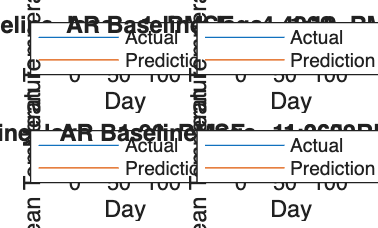

Model 1 (lags = [1]) RMSE = 4.430
Model 2 (lags = [1   2   3   4   5   6   7   8   9  10]) RMSE = 2.933
Model 3 (lags = [1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63  64  65  66  67  68  69  70  71  72  73  74  75  76  77  78  79  80  81  82  83  84  85  86  87  88  89  90]) RMSE = 11.962
Model 4 (lags = [1    2    3    4    5    6    7    8    9   10   11   12   13   14   15   16   17   18   19   20   21   22   23   24   25   26   27   28   29   30   31   32   33   34   35   36   37   38   39   40   41   42   43   44   45   46   47   48   49   50   51   52   53   54   55   56   57   58   59   60   61   62   63   64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98  

N = length(y_train);

% four lags
lagSets = { [1], 1:10, 1:90, 1:365 };

numModels = numel(lagSets);

figure;
for m = 1:numModels
    lags = lagSets{m};
    maxLag = max(lags);

    % Build X_train (lagged values) and Y_train (targets)
    X_train = zeros(N - maxLag, numel(lags));
    Y_train = y_train(maxLag+1:end);

    for j = 1:numel(lags)
        lag = lags(j);
        % For each lag, align so that row k uses y_train at time (maxLag - lag + k)
        X_train(:, j) = y_train(maxLag - lag + 1 : end - lag);
    end

    % Fit linear regression model (autoregressive with given lags)
    model = fitlm(X_train, Y_train);

    % Recursive prediction on the test set
    y_all = [y_train; zeros(size(y_test))];

    for t = 1:length(y_test)
        % Indices of the required past values for the current prediction
        idxPast = maxLag + t - lags;    % vector of indices
        lastVals = y_all(idxPast);      % past values according to the chosen lags
        lastVals = lastVals(:)';        % row vector for predict()
        pred = predict(model, lastVals);
        y_all(N + t) = pred;
    end

    pred_test = y_all(N+1:end);

    % Compute RMSE
    rmse = sqrt(mean((pred_test - y_test).^2));
    fprintf("Model %d (lags = [%s]) RMSE = %.3f\n", ...
        m, num2str(lags), rmse);

    % Plot results for each model
    subplot(2,2,m);
    plot(y_test, 'DisplayName', 'Actual'); hold on;
    plot(pred_test, 'DisplayName', 'Prediction');
    legend('Location','best');
    xlabel('Day');
    ylabel('Mean Temperature');
    grid on;
    if numel(lags) > 1 && all(diff(lags) == 1)
        lagStr = sprintf('%d:%d', lags(1), lags(end));
    else
        lagStr = sprintf('%s', num2str(lags));
    end
    title(sprintf('AR Baseline, lags = %s, RMSE = %s', lagStr, num2str(rmse)));
end